% 定义参数
V = 1.0;
G = 45.0;
k = 0.7;
a0 = 6.0;
n = 5;

% 初始化猜测
initial_guess = [5; 4; 3; 2; 1];

% 设置收敛容限和最大迭代次数
tolerance = 1e-12;
max_iterations = 500;

% 调用梯度下降方法求解
[x_gradient, f_gradient] = gradientDescentL(@nonlinear_equations_for_question_e, initial_guess, tolerance, max_iterations, V, G, k);

 it     |f(x)|
 0    17.790166
     alpha       |f(x)|
     1.0000    13.895692
 1    13.895692
     alpha       |f(x)|
     1.0000    16.783623
     0.5000     8.711487
 2     8.711487
     alpha       |f(x)|
     1.0000    10.123735
     0.5000     9.417537
     0.2500     9.064492
     0.1250     8.887984
     0.0625     8.799734
     0.0312     8.755610
     0.0156     8.733549
     0.0078     8.722518
     0.0039     8.717002
     0.0020     8.714245
     0.0010     8.712866
     0.0005     8.712176
     0.0002     8.711832
     0.0001     8.711659
     0.0001     8.711573
     0.0000     8.711530
     0.0000     8.711509
     0.0000     8.711498
     0.0000     8.711492
     0.0000     8.711490
     0.0000     8.711488
   Reached maxSteps on this Newton step
 3     8.711488
     alpha       |f(x)|
     1.0000    10.123736
     0.5000     9.417539
     0.2500     9.064493
     0.1250     8.887985
     0.0625     8.799735
     0.0312     8.755612
     0.0156     8.733550
     0.007


% 显示结果
disp('Gradient Descent Method:');

Gradient Descent Method:


disp(['Numerical Solution: ', num2str(x_gradient')]);

Numerical Solution: 6.5005 -5.0016e-07 -4.9958e-07 -4.9988e-07 -4.9974e-07


disp(['Function Value at Numerical Solution: ', num2str(norm(f_gradient))]);

Function Value at Numerical Solution: 8.7122


 it     |f(x)|
 0    17.790166
     alpha       |f(x)|
     1.0000     5.117917
 1     5.117917
     alpha       |f(x)|
     1.0000     1.131354
 2     1.131354
     alpha       |f(x)|
     1.0000     0.184373
 3     0.184373
     alpha       |f(x)|
     1.0000     0.013656
 4     0.013656
     alpha       |f(x)|
     1.0000     0.000135
 5     0.000135
     alpha       |f(x)|
     1.0000     0.000000
 6     0.000000
     alpha       |f(x)|
     1.0000     0.000000
 7     0.000000
 SUCCESS: Converged


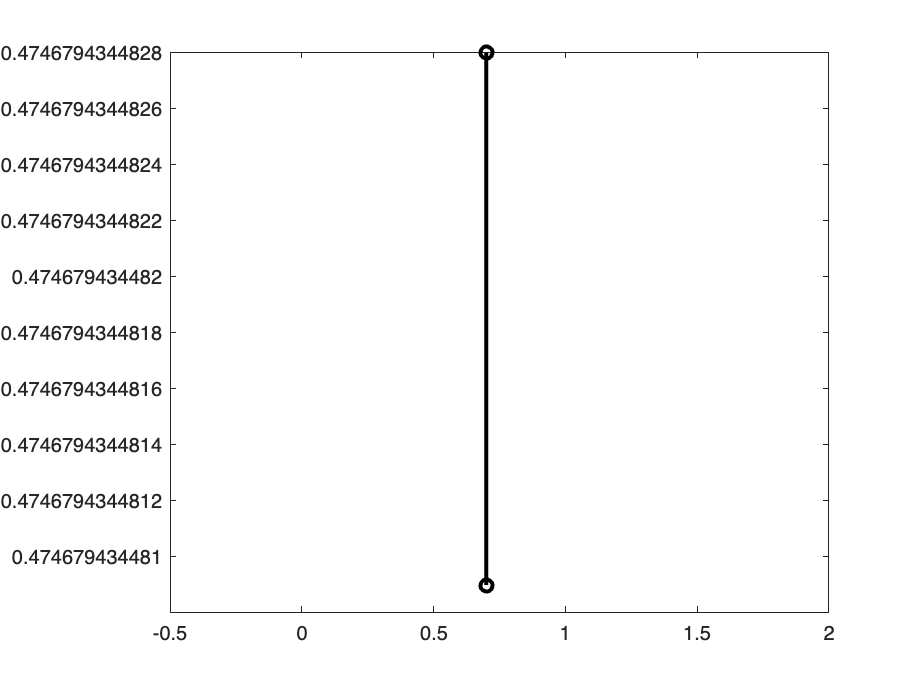


% 调用牛顿法求解作为对比
[x_newton, f_newton] = newtonSysL(@nonlinear_equations_for_question_e, @calculateJacobian, initial_guess, tolerance, max_iterations, V, G, k);

disp('Newton''s Method:');

Newton's Method:


disp(['Numerical Solution: ', num2str(x_newton')]);

Numerical Solution: 0.7     0.47468     0.35128     0.27542     0.22486


disp(['Function Value at Numerical Solution: ', num2str(norm(f_newton))]);

Function Value at Numerical Solution: 1.2228e-14
